# Structure preserving Krylov subspace methods

## How it works

### Projective Model Order Reduction

Projective model order reduction methods use matrices $V$ and $W$ to project the dynamic system of equations $\Sigma$


$$E\dot x = Ax + Bu\\
y = Cx + Du$$



$$x \in \mathbb{R}^n,~A \in \mathbb{R}^{n\times n},~ B \in \mathbb{R}^{n\times p}, ~C \in \mathbb{R}^{q\times n}, ~D \in \mathbb{R}^{q\times p}$$


to a lower dimensional subspace $\tilde{\mathcal{V}} = range(V)$ along the directions orthogonal to $\tilde{\mathcal{W}} = range(W)$. 

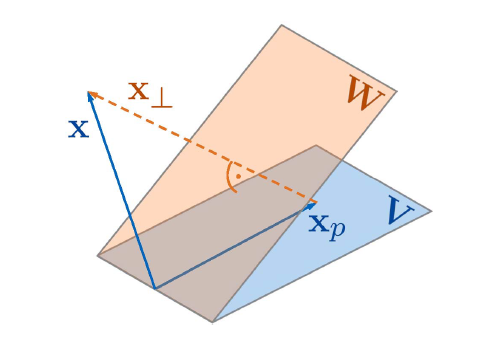

For this, the projector $\Pi = V(W^TV)^{-1}W^T$ and new coordinates $\tilde{x} \in \mathbb{R}^m,~m<<n$ are used such that $x \approx V\tilde{x}$.

The resulting reduced system $\tilde{\Sigma}$ is


$$\tilde{E}\dot{\tilde{x}} = \tilde{A}\tilde{x} + \tilde{B}u\\
y = \tilde{C}x + \tilde{D}u$$



$$x \in \mathbb{R}^m,~A \in \mathbb{R}^{m\times m},~ B \in \mathbb{R}^{m\times p}, ~C \in \mathbb{R}^{q\times m}, ~D \in \mathbb{R}^{q\times p}$$


where

$\tilde{A} = W^TAV,~\tilde{E} = W^TEV,~\tilde{B} = W^TB,~\tilde{C} = CV,~\tilde{D} = D$.

### Finding V and W: Krylov subspaces

Our goal is to find $\tilde{\Sigma}$ such that it approximates the dynamic behavior ($u \rightarrow y$) of the original system $\Sigma$ well. Krylov subspace methods provide one solution for this problem.

The idea is that the reduced model approximates the **power series expansion of the transfer function** $G(s)$ of $\Sigma$ at  so-called '**shifts**' $\sigma$


$$G(s) = \sum_{j = 0}^{\infty} \mu_j (s-\sigma)^j$$


where the $\mu_j$ are the '**moments**' of $G(s)$.

In case of linear time-invariant systems, the moments are:


$$\mu_j = C^T((A-\sigma E)^{-1}E)^j (A-\sigma E)^{-1} B$$


For approximation, we use **Krylov subspaces** $\mathcal{K}_d(M,m) := span(m,Mm, M^2m, ..., M^{d-1}m)$ (dimension $d$, Matrix $M$, vector $m$):

If we choose $V$ and/or $W$ such that


$$\bigcup_{k=1}^{K} \mathcal{K}_{j_{k_b}}((A-\sigma_kE)^{-1}E, (A-\sigma_kE)^{-1}B) \subseteq span(V)\\
\bigcup_{k=1}^{K} \mathcal{K}_{j_{k_c}}((A-\sigma_kE)^{-T}E^T, (A-\sigma_kE)^{-T}C^T) \subseteq span(W)$$


it can be shown that the moments of the original system $\mu_{j_k}$ and of the reduced system and $\tilde{\mu}_{j_k}$ at shift $\sigma_k$ are equal for $j_k = 0,~1,~...,~({j_{k_b}} + {j_{k_c}} - 1)$ ('moment matching') [1].

The remaining problem is to find appropriate shifts $\sigma_k$ which reflect the dynamic behavior. A very popular algorithm which solves this problem iteratively is called '*Iterative Rational Krylov Algorithm*' (IRKA) for which suitable adaptations for PH systems exist (see also [demo_irkaPH](matlab: edit demo_irkaPH.mlx)).

For a more detailed introduction, we suggest [1], [6].

### Structure preserving reduction

Finding both matrices $V$ and $W$ as indicated above does in general not preserve the structure of port-Hamiltonian system models


$$E\dot{x} = (J-R) Q x + (G-P)u\\ y = (G+P)^TQx + (S+N) u$$


We will give up some approximation accuracy by not using $W$ for moment matching but structure preservation instead. $W$ is chosen such that (skew-) symmetry properties and potential positive (semi-) definiteness of $J$, $R$, and $Q$ are retained. We will introduce some of the options from the literature below.

#### (1) Scaling

Assuming that the energy matrix of our original system $Q$ and the descriptor matrix $E$ equal the identity matrix, i.e. our system now has the form


$$\dot{x} = (J-R) x + (G-P)u\\ y = (G+P)^Tx + (S+N) u$$


and $V$ is orthogonal ($V^TV = I$), we can set $W := V$, $\tilde{J} = W^TJV$,  $\tilde{R} = W^TRV$,  $\tilde{G} = W^TG$, $\tilde{P} = W^TP$, $\tilde{S} = S,~\tilde{N} = N$ to obtain a reduced PH model. [2]

#### (2) 'Special Inverse'

Choosing $W := QV(V^TQV)^{-1}$ and setting $\tilde{J} = W^TJW$,  $\tilde{R} = W^TRW$, $\tilde{Q} = V^TQV$, $\tilde{E} = W^TEV$, $\tilde{G} = W^TG$, $\tilde{P} = W^TP$, $\tilde{S} = S,~\tilde{N} = N$ leads to a port-Hamiltonian reduced order model (ROM) [4].

#### (3) Cholesky decomposition

This solution first computes the Cholesky decomposition $L$ of $V^TQV$: $L^TL = V^TQV$

Without losing the moment matching property, we can define a new projection matrix $\hat{V} := VL^{-1}$. $\hat{W}$ is then defined as $\hat{W} := Q\hat{V}$. The reduced system matrices are

$\tilde{J} = \hat{W}^TJQ\hat{V}$, $\tilde{R} = \hat{W}^TRQ\hat{V}$, $\tilde{Q} = I$, $\tilde{E} = \hat{W}^TE\hat{V}$, $\tilde{G} = \hat{W}^TG$, $\tilde{S} = S,~\tilde{N} = N$  [3].

For explicit systems, this also yields an explicit reduced order model. 

**Extension**: Instead of the above definition of $L$, we can also use $L^TL = V^TQ^TEV$ and obtain

$\tilde{J} = \hat{W}^TJQ\hat{V}$, $\tilde{R} = \hat{W}^TRQ\hat{V}$, $\tilde{Q} = I$, $\tilde{E} = I$, $\tilde{G} = \hat{W}^TG$, $\tilde{S} = S,~\tilde{N} = N$.

This yields an explicit ROM for both explicit and implicit original models.

#### (4) QV

One of the computationally easiest solution is defining $W := QV$ and computing

$\tilde{J} = \hat{W}^TJQ\hat{V}$, $\tilde{R} = \hat{W}^TRQ\hat{V}$, $\tilde{Q} = I$, $\tilde{E} = \hat{W}^TE\hat{V}$, $\tilde{G} = \hat{W}^TG$, $\tilde{S} = S,~\tilde{N} = N$ [5]. 

Here, the resulting system is not in explicit form even if the original system was.

## Toolbox Implementation

The toolbox offers ***arnoldiPH ***- an implementation of the Arnoldi algorithm (an algorithm which applies Krylov subspace reduction with orthogonal matrices $V$ and $W$) which is specialized for port-Hamiltonian system models, i.e. it retains the structure as presented above. It takes as inputs the system *sys* to be reduced (*phs*-object), the vector of shifts *s0* and matrix of tangent directions *b* (only MIMO) as well as an optional struct *Opts* which allows to control the algorithms behavior.

help arnoldiPH

  arnoldiPH - reduces the system sys by the rational Arnoldi algorithm with
            interpolation points specified in s0.
 
  Syntax:
    redSys = arnoldiPH(sys, s0)
    redSys = arnoldiPH(sys, s0, Opts)
    redSys = arnoldiPH(sys, s0, b)
    redSys = arnoldiPH(sys, s0, b, Opts)
    [redSys,V,W,nLU] = arnoldiPH(sys, ...)
 
  Description:
        redSys = arnoldiPH(sys, s0) returns the reduced system redSys. It
        computes the ROM by interpolation of the transfer function with
        Krylov subspaces. The Arnoldi method has been adapted to PH systems
        (see References).
        The reduced system order will be as high as the number of
        interpolation points in s0 for real shifts. Imaginary shifts can be
        passed as complex conjugate values - if they are unique, the
        algorithm will complement the complex conjugate shifts.
 
        redS

One of the most important options is *Opts.structurePreservation* which allows to choose from five different ways of preserving the structure (see section above).

The algorithm calls the subfunction *computeV *(or the function *arnoldi* from the sssMOR toolbox, if requested) to obtain a moment matching subspace matrix $V$. It then calls the utility function *structurePreservation* which applies $V$ to obtain $W$ and the reduced system matrices of a port-Hamiltonian system.

help structurePreservation

  structurePreservation - Returns reduced system matrices of sys with V by
        application of PH structure preserving compuations
 
  Syntax:
    [J_red, R_red, Q_red, G_red, E_red, P_red, S_red, N_red, V, W]
                                    = structurePreservation(sys, V, Opts)
 
  Description:
        This function uses the Krylov-subspace matrix V (possibly obtained
        by the arnoldi algorithm) to compute reduced system matrices J_red,
        R_red, etc. of a reduced port-Hamiltonian system. The structure
        preservation mechanism can be set by Opts.structurePreservation
        (see Input Arguments below).
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  phs object which is to be reduced
        - V:    Krylov subspace matrix, should be orthogonal
        - Opts: structure with execution parameters
            - .structurePreservation: determines how structure is
          

## Examples

We will now reduce a mass-spring-damper system in port-Hamiltonian system notation. The system is constructed as follows:

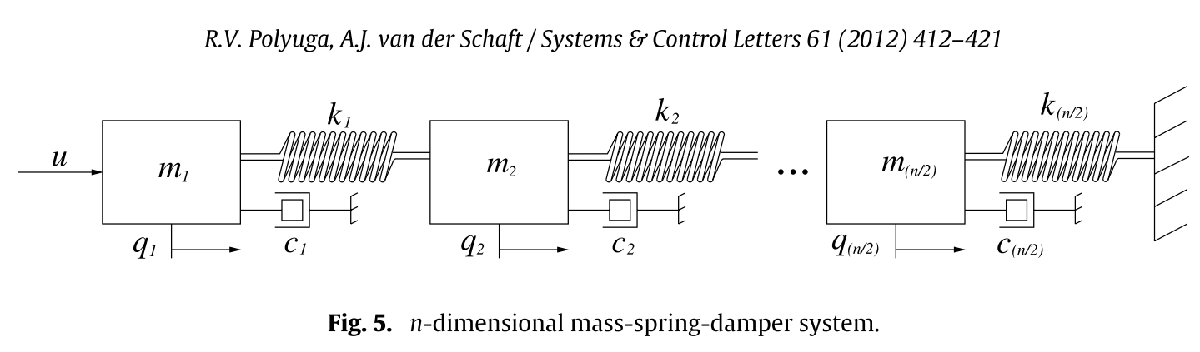

Image source: [7]

Our system has order 100, i.e. 50 masses (m = 2), 50 springs (k = 1), and 50 dampers (c = 1):

sys = setup_MassSpringDamperSystem(100,2,1,1,'SISO')

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×1 double]
               E: [100×100 double]
               P: [100×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


In the following, the system will be reduced with different choices of shifts.

We set up some basic options for the algorithm (if not provided, the algorithm will choose default values):

Opts.constAlg = 'phs';  % Use computeV (default)
Opts.orth = '2mgs';     % Orthogonalization by double application of Gram-Schmidt procedure
Opts.reorth = true;     % Reorthogonalization of columns of V before structure preservation
Opts

Opts = struct with fields:
                 constAlg: 'phs'
                     orth: '2mgs'
                   reorth: 1
    structurePreservation: 'Cholesky+'


### Logspace shifts

First, we choose 10 logarithmically distributed shifts on a range from $10^{-5}$ to $10^5$

shifts_log = logspace(-5,5,10)

shifts_log = 	1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0060    0.0774    1.0000


and run the algorithm with structure preservation Scaling:

Opts.structurePreservation = 'scaling';
redSys_log = arnoldiPH(sys,shifts_log,Opts)

redSys_log =   phsRed with properties:

      parameters: [1×1 struct]
          method: @arnoldiPH
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


We can compare the original and the reduced system by having a look at the bode plots:

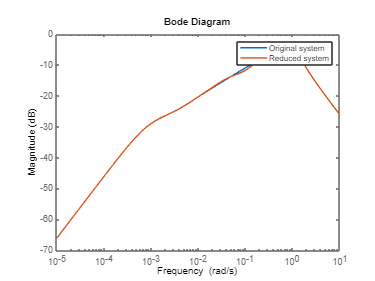

bodemag(sys,redSys_log);
legend('Original system','Reduced system')

### Zero shifts

We repeat the procedure with 10 shifts at zero and structure preservation 'Special Inverse':

shifts_zero = zeros(10,1)

shifts_zero =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Opts.structurePreservation = 'specialInverse';  % W = QV(V^TQV)^(-1)
redSys_zero = arnoldiPH(sys,shifts_zero,Opts)

redSys_zero =   phsRed with properties:

      parameters: [1×1 struct]
          method: @arnoldiPH
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


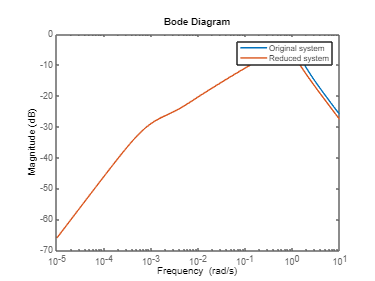

bodemag(sys,redSys_zero);
legend('Original system', 'Reduced system')

As we might have expected, this vector of shifts leads to a better approximation at small frequencies at decreased accuracy at higher frequencies.

### Infinity Shifts

Next, we will use shifts at infinity and Cholesky structure preservation:

shifts_inf = Inf(10,1)

shifts_inf =    Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf
   Inf


Opts.structurePreservation = 'Cholesky'; 
redSys_inf = arnoldiPH(sys,shifts_inf,Opts)

redSys_inf =   phsRed with properties:

      parameters: [1×1 struct]
          method: @arnoldiPH
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


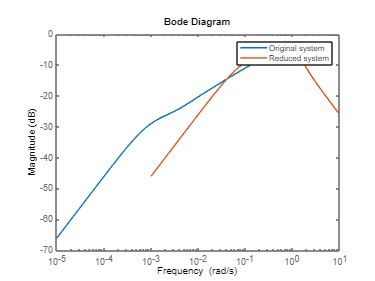

bodemag(sys,redSys_inf);
legend('Original system', 'Reduced system')

This is a complementary result to 'zero shifts'.

### Imaginary shifts

Imaginary shifts can be used to match the transfer function / the bode plot (= imaginary) exactly at certain frequencies.

shifts_imag = 1i*shifts_log

shifts_imag = 	1.0e+05 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0005i   0.0000 + 0.0060i   0.0000 + 0.0774i   0.0000 + 1.0000i


Opts.structurePreservation = 'Cholesky+'; % Extension of Cholesky
redSys_imag = arnoldiPH(sys,shifts_imag,Opts)

redSys_imag =   phsRed with properties:

      parameters: [1×1 struct]
          method: @arnoldiPH
            info: []
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×1 double]
               E: [20×20 double]
               P: [20×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


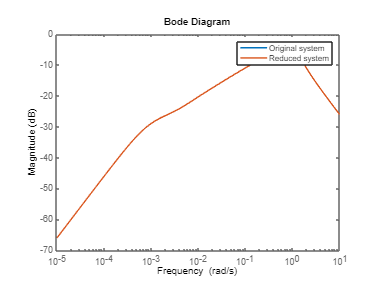

bodemag(sys,redSys_imag);
legend('Original system', 'Reduced system')

**Note:** The obtained system has order 20 because the algorithm **automatically extends vectors of complex shifts** to **complex conjugate pairs**. Since our initial vector has 10 not complex conjugate shifts, it is doubled by the algorithm. Thus, accuracy is also superior to previous examples.

## A closer look at the output

The output of the *arnoldiPH* algorithm gives some additional information:

shifts = [shifts_log,shifts_log]

shifts = 	1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0060    0.0774    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0060    0.0774    1.0000


[redSys, V, W, nLU] = arnoldiPH(sys,shifts,Opts);

V and W are the matrices which were used for reduction. nLU is the number of LU decompositions which are required for computing V (Not all LU decompositions are necessarily performed as the Backslash-operator is preferred for single shifts.)

whos V W

  Name        Size            Bytes  Class     Attributes

  V         100x20            16000  double              
  W         100x20            16000  double              



nLU

nLU = 10

Here, nLU is only 10 (not equal to number of shifts!) because the LU decompositions can be reused for 2 shifts, each.

The reduced system also provides some information on how it was created:

whos redSys

  Name        Size            Bytes  Class     Attributes

  redSys      1x1             15405  phsRed              



redSys.method   % Method used for reduction

ans = function_handle with value:
    @arnoldiPH


redSys.parameters

ans = struct with fields:
                 constAlg: 'phs'
                     orth: '2mgs'
                   reorth: 1
    structurePreservation: 'Cholesky+'
                      lse: 'sparse'
                  verbose: 1
                      phs: [1×1 struct]
                   shifts: [1.0000e-05 1.2915e-04 0.0017 0.0215 0.2783 3.5938 46.4159 599.4843 7.7426e+03 100000 1.0000e-05 1.2915e-04 0.0017 0.0215 0.2783 3.5938 46.4159 599.4843 7.7426e+03 100000]


## MIMO systems

Krylov subspace algorithms are also capable of reducing multiple-input multiple-output (MIMO) systems. Since the transfer function $G(s)$ is now a $q \times p$ matrix, two approaches of moment matching have evolved.

### Block-Krylov

The Krylov-subspace interpolation property is still valid for MIMO systems [1]. Instead of finding only one row of $V$ at a time (SISO case), we will now find $p$ (or $q$) column entries.

### Tangent directions

Another approach is to match moments along certain directions, called '**tangent directions**'. The condition we want to satisfy now becomes


$$\mu_j t_j = \tilde{\mu}_j t_j$$


for a set of tangent directions $t_j \in \mathbb{R}^{p}$.

### Example

sys = setup_MassSpringDamperSystem(100,2,1,1,'MIMO')

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×2 double]
               E: [100×100 double]
               P: [100×2 double]
               S: [2×2 double]
               N: [2×2 double]
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 1
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


shifts = logspace(-5,5,10)

shifts = 	1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0060    0.0774    1.0000


tangent = ones(size(sys.G,2),length(shifts))

tangent =      1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


redSys_block = arnoldiPH(sys,shifts)

redSys_block =   phsRed with properties:

      parameters: [1×1 struct]
          method: @arnoldiPH
            info: []
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×2 double]
               E: [20×20 double]
               P: [20×2 double]
               S: [2×2 double]
               N: [2×2 double]
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 1
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


redSys_tangent = arnoldiPH(sys,shifts,tangent)

redSys_tangent =   phsRed with properties:

      parameters: [1×1 struct]
          method: @arnoldiPH
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×2 double]
               E: [10×10 double]
               P: [10×2 double]
               S: [2×2 double]
               N: [2×2 double]
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 1
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


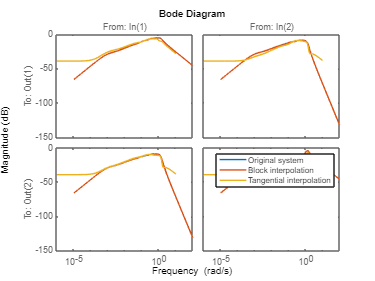

bodemag(sys,redSys_block,redSys_tangent)
legend('Original system','Block interpolation','Tangential interpolation')

Accuracy of the block interpolation is expectedly higher because it has a two times higher dimension (factor $p = 2$). Accuracy of the tangential interpolation model could be improved by finding better tangential directions (= new degree of freedom).

sys.dim

ans = 100

redSys_block.dim

ans = 20

redSys_tangent.dim

ans = 10

## References

[1] Eric James Grimme (1997), *Krylov Projection Methods for Model Reduction*, Thesis, University of Illinois at Urbana-Champaign.

[2] Polyuga (2010), *Model Reduction of Port-Hamiltonian Systems*, Thesis, University of Groningen

[3] Gugercin et al. (2009),* Interpolation-based *$\mathcal{H}_2$* model reduction for port-Hamiltonian systems*, in Proceedings of the 48th IEEE Conference on Decision and Control (CDC) held jointly with 2009 28th Chinese Control Conference

[4] S. Gugercin, Rostyslav V. Polyuga, C. Beattie, and A. van der Schaft. Structure-preserving tangential interpolation for model reduction of port-Hamiltonian systems. *Automatica J. IFAC*, 48(9):1963–1974, 2012.

[5] T. Wolf, B. Lohmann, R. Eid, and P. Kotyczka. Passivity and structure preserving order reduction of linear port-Hamiltonian systems using Krylov subspaces. *Eur. J. Control*, 16(4):401–406, 2010.

[6] A. C. Antoulas. *Approximation of large-scale dynamical systems*. Advances in Design and Control. Society for Industrial and Applied Mathematics, Philadelphia, PA, USA, 2005.

[7] R. V. Polyuga and A. van der Schaft. Effort- and flow-constraint reduction methods for structure-preserving model reduction of port-Hamiltonian systems. *Systems Control Letters*, 61(3):412–421, 2012.  

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Julius Durmann    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)